clc;
close all;
clear all;

beats=75;%beats per minute, static body
% beats=170;%beats per minute, dynamic body
f_heart=beats/60;

sample_time=10^(-2);
stop_time=15;

% left_ventricle_pressure=horzcat(sample_time*(0:n2-n1)',out.P_LV.Data(n1:n2));
% stop_time=out.P_LV.Time(n2)-out.P_LV.Time(n1)+1;

%Rydeout1991mathematical
CGS_units=1332;
P_AT=6*CGS_units;
P_SV=3*CGS_units;
%resistors
R_AT=8;
R_LV=5;
R_SA=200;
R_CA=1250;
R_AO=5;
%capacitors
C_CA=0.0022;
C_AO=0.00015;
C_SA=0.0003;
Q_SAIC=281*60;%mAh
Q_LVIC=0;%120*60;%mAh
%inductors
L_AO=0.5;
L_LV=0.5;


%Generator Parameters
S_LS=2500;
S_LD=75;
T_H=1/f_heart;%heart period
T_S=0.3/0.8*T_H;%duration of systole proportionally to the case when beats=75, static
B=1.05;
gen_time=0:sample_time:T_H;
gen_val=B*(S_LS-S_LD)*horzcat(sin(pi*1/T_S*(0:sample_time:T_S)),zeros(1,round((T_H-T_S)/sample_time)))+S_LD;
%clipping
gen_val(find(gen_val>=S_LS))=S_LS;

%peripherical resistances
R_24=32.4*10^3;
R_26=64.8*10^3;
R_29=32.4*10^3;
R_34=170*10^3;
R_35=78*10^3;
R_51=R_26;
R_54=R_29;
R_59=R_34;
R_60=23.1*10^3;
R_61=10.8*10^3;
R_62=R_60;
R_64=36.8*10^3;
R_65=32.4*10^3;
R_66=69.5*10^3;
R_70=162*10^3;
R_82=126*10^3;
R_84=126*10^3;
R_88=103*10^3;
R_90=400*10^3;
R_102=R_82;
R_105=162*10^3;
R_107=R_84;
R_111=R_88;
R_113=R_90;

opts=detectImportOptions('Parameters.xlsx');
% preview('Parameters.xlsx',opts) %data file preview

opts.SelectedVariableNames=[1,3:5];
table=readmatrix('Parameters.xlsx',opts);

R=-ones(1,max(table(:,1)))';
L=-ones(1,max(table(:,1)))';
C=-ones(1,max(table(:,1)))';

for i=1:length(table(:,1))
    R(table(i,1))=table(i,2);
    L(table(i,1))=table(i,3)*10^(0);
    C(table(i,1))=table(i,4)*10^(-6);
end


### Obtaining the T matrices for each block

f_heart_vector=linspace(30,220,100)/60;
H_num_A=zeros(length(f_heart_vector),max(table(:,1)),4);
H_den_A=zeros(length(f_heart_vector),max(table(:,1)),4);

for k=1:length(f_heart_vector)
    
    T_matrix_struct=struct([]);
    %matrix of impedances
    Z_out=(1+1i)*ones(1,max(table(:,1)));
    
    for i=1:length(table(:,1))
        j=table(i,1);
        T_matrix_struct{j}=zs2t(R(j))*zs2t(1i*2*pi*f_heart_vector(k)*L(j))*yp2t(1i*2*pi*f_heart_vector(k)*C(j));
    end

### Obtaining the load impedances per block

    %saving the terminators loads
    R_o=[R_26 R_29 R_34 R_35 R_51 R_54 R_59 R_60 R_61 R_62 R_64 R_65 R_66 R_70 R_82 R_84 R_88 R_90 R_102 R_105];
    R_o_index=[26 29 34 35 51 54 59 60 61 62 64 65 66 70 82 84 88 90 102 105];
    for i=1:length(R_o)
        j=R_o_index(i);
        Z_out(j)=R_o(i);
    end
    
    %Upper arms
    %computing impedances starting at the Ulnaris
    Z_out(81)=abcd2Zin(T_matrix_struct{82},R_82);
    Z_out(80)=abcd2Zin(T_matrix_struct{81},Z_out(81));
    Z_in(80)=abcd2Zin(T_matrix_struct{80},Z_out(80));
    
    % T_Ulnaris_1=T_matrix_struct{80}*T_matrix_struct{81}*T_matrix_struct{82};
    %Volaris
    Z_out(89)=abcd2Zin(T_matrix_struct{90},R_90);
    Z_in(89)=abcd2Zin(T_matrix_struct{89},Z_out(89));
    
    Z_out(79)=parallImp(Z_in(89),Z_in(80));
    
    %Radialis
    Z_out(87)=abcd2Zin(T_matrix_struct{88},R_88);
    Z_out(86)=abcd2Zin(T_matrix_struct{87},Z_out(87));
    Z_out(85)=abcd2Zin(T_matrix_struct{86},Z_out(86));
    
    %Brachialis
    Zin_85=abcd2Zin(T_matrix_struct{85},Z_out(85));
    Zin_79=abcd2Zin(T_matrix_struct{79},Z_out(79));
    Z_out(78)=parallImp(Zin_79,Zin_85);
    Z_out(77)=abcd2Zin(T_matrix_struct{78},Z_out(78));
    Z_out(76)=abcd2Zin(T_matrix_struct{77},Z_out(77));
    Z_out(75)=abcd2Zin(T_matrix_struct{76},Z_out(76));
    Zin_75=abcd2Zin(T_matrix_struct{75},Z_out(75));
    
    %Axillaris
    Z_out(74)=abcd2Zin(T_matrix_struct{75},Z_out(75));
    Z_out(73)=abcd2Zin(T_matrix_struct{74},Z_out(74));
    Zin_73=abcd2Zin(T_matrix_struct{73},Z_out(73));
    
    %Subclavia
    Z_out(72)=abcd2Zin(T_matrix_struct{73},Z_out(73));
    Zin_72=abcd2Zin(T_matrix_struct{72},Z_out(72));
    
    %Vertebralis
    Z_out(83)=abcd2Zin(T_matrix_struct{84},R_84);
    Zin_83=abcd2Zin(T_matrix_struct{83},Z_out(83));
    Z_out(71)=parallImp(Zin_72,Zin_83);
    Zin_71=abcd2Zin(T_matrix_struct{71},Z_out(71));
    
    %Carotis Comunis
    Z_out(69)=abcd2Zin(T_matrix_struct{70},R_70);
    Z_out(68)=abcd2Zin(T_matrix_struct{69},Z_out(69));
    Z_out(67)=abcd2Zin(T_matrix_struct{68},Z_out(68));
    Zin_67=abcd2Zin(T_matrix_struct{67},Z_out(67));
    
    Z_UpperBody=parallImp(Zin_67,parallImp(Zin_71,Zin_71));
    
    %Legs
    %Tibialis Posterior
    i=25;
    while i>=22
        Z_out(i)=abcd2Zin(T_matrix_struct{i+1},Z_out(i+1));
        i=i-1;
    end
    Zin_22=abcd2Zin(T_matrix_struct{22},Z_out(22));
    
    %Tibialis Anterior
    i=33;
    while i>=30
        Z_out(i)=abcd2Zin(T_matrix_struct{i+1},Z_out(i+1));
        i=i-1;
    end
    Zin_30=abcd2Zin(T_matrix_struct{30},Z_out(30));
    
    %Femoralis & Poplitea
    Z_out(21)=parallImp(Zin_22,Zin_30);
    i=20;
    while i>=15
        Z_out(i)=abcd2Zin(T_matrix_struct{i+1},Z_out(i+1));
        i=i-1;
    end
    Zin_15=abcd2Zin(T_matrix_struct{15},Z_out(15));
    
    %Profundis Femoris
    i=28;
    while i>=27
        Z_out(i)=abcd2Zin(T_matrix_struct{i+1},Z_out(i+1));
        i=i-1;
    end
    Zin_27=abcd2Zin(T_matrix_struct{27},Z_out(27));
    Z_out(14)=parallImp(Zin_15,Zin_27);
    
    %Iliaca Communis & Externa
    i=13;
    while i>=11
        Z_out(i)=abcd2Zin(T_matrix_struct{i+1},Z_out(i+1));
        i=i-1;
    end
    Zin_11=abcd2Zin(T_matrix_struct{11},Z_out(11));
    
    %Mesenteric Inferior
    Zin_35=abcd2Zin(T_matrix_struct{35},Z_out(35));
    
    %Center Body
    %Aorta Abdominalis
    Z_out(10)=parallImp(Zin_35,parallImp(Zin_11,Zin_11));
    Z_out(9)=abcd2Zin(T_matrix_struct{10},Z_out(10));
    Zin_9=abcd2Zin(T_matrix_struct{9},Z_out(9));
    Zin_60=abcd2Zin(T_matrix_struct{60},Z_out(60));
    Zin_61=abcd2Zin(T_matrix_struct{61},Z_out(61));
    Zin_62=abcd2Zin(T_matrix_struct{62},Z_out(62));
    Z_out(8)=parallImp(Zin_60,parallImp(Zin_61,parallImp(Zin_62,Zin_9)));
    Zin_8=abcd2Zin(T_matrix_struct{8},Z_out(8));
    %Thorax Aorta
    Zin_64=abcd2Zin(T_matrix_struct{64},Z_out(64));
    Zin_65=abcd2Zin(T_matrix_struct{65},Z_out(65));
    Zin_66=abcd2Zin(T_matrix_struct{66},Z_out(66));
    Z_out(63)=parallImp(Zin_64,parallImp(Zin_65,Zin_66));
    Zin_63=abcd2Zin(T_matrix_struct{63},Z_out(63));
    Z_out(7)=parallImp(Zin_8,Zin_63);
    
    %Thorax and Arcus Aorta
    i=6;
    while i>=4
        Z_out(i)=abcd2Zin(T_matrix_struct{i+1},Z_out(i+1));
        i=i-1;
    end
    Zin_4=abcd2Zin(T_matrix_struct{4},Z_out(4));
    
    %Arcus Aorta
    Z_out(3)=parallImp(Zin_4,Z_UpperBody);

    while i>=1
        Z_out(i)=abcd2Zin(T_matrix_struct{i+1},Z_out(i+1));
        i=i-1;
    end
    
    Zin_1=abcd2Zin(T_matrix_struct{1},Z_out(1));
    

### Obtaining the frequency response for circuit block

     for i=1:length(table(:,1))
        j=table(i,1);
        if(j==2)
            p=1;
        end
        %analog domain
        %resistive or inductive load
        if (imag(Z_out(j))>=0)
            R_in=real(Z_out(j));
            L_in=imag(Z_out(j))/2/pi/f_heart_vector(k);
            %numerator
            b1A=L_in;
            b0A=R_in;
            %denominator
            a3A=C(j)*L(j)*L_in;
            a2A=C(j)*L(j)*R_in + C(j)*L_in*R(j);
            a1A=L(j) + L_in + C(j)*R(j)*R_in;
            a0A=R(j) + R_in;
            
            b=[0,0,b1A,b0A];
            a=[a3A,a2A,a1A,a0A];
        end
        %capacitance load
        if (imag(Z_out(j))<0)
            R_in=real(Z_out(j));
            C_in=-1/imag(Z_out(j))/2/pi/f_heart_vector(k);
            %numerator
            b1A=C_in*R_in;
            b0A=1;
            %denominator
            a3A=C(j)*C_in*L(j)*R_in;
            a2A=C(j)*L(j) + C_in*L(j) + C(j)*C_in*R(j)*R_in;
            a1A=C(j)*R(j) + C_in*R(j) + C_in*R_in;
            a0A=1;
            
            b=[0,0,b1A,b0A];
            a=[a3A,a2A,a1A,a0A];
        end

        H_num_A(k,j,:)=reshape(b,1,1,length(b));
        H_den_A(k,j,:)=reshape(a,1,1,length(a));
    
     end

end

#### Plotting the frequency response

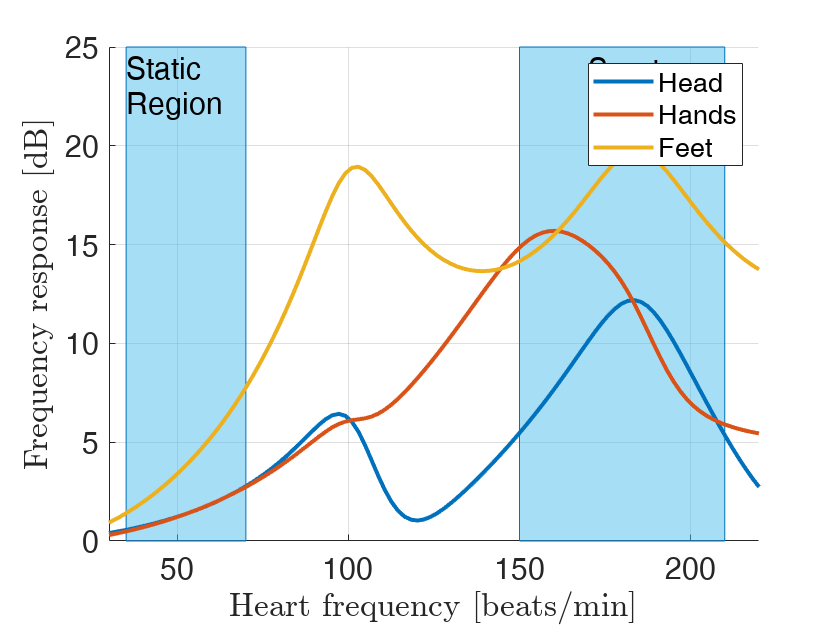

figure;
fontsize=15;

y_lim=25;
p=patch([35 70 70 35],[0 0 y_lim y_lim],[0.3010 0.7450 0.9330],"EdgeColor",'#0072BD');hold on;
set(p,'FaceAlpha',0.5);
p=patch([150 210 210 150],[0 0 y_lim y_lim],[0.3010 0.7450 0.9330],"EdgeColor",'#0072BD');hold on;
set(p,'FaceAlpha',0.5);

y_txt=23;
ht=text(35, y_txt+0.01,{'Static','Region'},'FontSize',fontsize);
ht=text(170, y_txt,{'Sport','Region'},'FontSize',fontsize);


%Head
%traveling through the head through the carotis comunis
circ=horzcat(1:7,67:70);
H_j=zeros(1,length(f_heart_vector));
H=ones(1,length(f_heart_vector));

for j=1:length(circ)
    for k=1:length(f_heart_vector)
        w=f_heart_vector(k)*2*pi;
        s = 1j*w;
        H_j(k) = abs(polyval(reshape(H_num_A(k,circ(j),:),1,4),s))/abs(polyval(reshape(H_den_A(k,circ(j),:),1,4),s));

    end
    H=H.*H_j;
    %plot(f_heart_vector,(H_j),'LineWidth',2);hold on;

end
p_1=plot(f_heart_vector*60,mag2db(abs(H)),'LineWidth',2); grid on; hold on;

%Hands
%traveling to the hands
circ=horzcat(1:3,71:82);
H_j=zeros(1,length(f_heart_vector));
H=ones(1,length(f_heart_vector));

for j=1:length(circ)
    for k=1:length(f_heart_vector)
        w=f_heart_vector(k)*2*pi;
        s = 1j*w;
        H_j(k) = abs(polyval(reshape(H_num_A(k,circ(j),:),1,4),s))/abs(polyval(reshape(H_den_A(k,circ(j),:),1,4),s));

    end
    H=H.*H_j;

end
p_2=plot(f_heart_vector*60,mag2db(abs(H)),'LineWidth',2);

%Legs
%traveling through the thorax till the feet
circ=1:26;
H_j=zeros(1,length(f_heart_vector));
H=ones(1,length(f_heart_vector));

for j=1:length(circ)
    for k=1:length(f_heart_vector)
        w=f_heart_vector(k)*2*pi;
        s = 1j*w;
        H_j(k) = abs(polyval(reshape(H_num_A(k,circ(j),:),1,4),s))/abs(polyval(reshape(H_den_A(k,circ(j),:),1,4),s));

    end
    H=H.*H_j;

end
p_3=plot(f_heart_vector*60,mag2db(abs(H)),'LineWidth',2);

xlabel('Heart frequency [beats/min]','Interpreter','latex');
ylabel('Frequency response [dB]','Interpreter','latex');
axis([f_heart_vector(1)*60 f_heart_vector(end)*60 0 y_lim]);
set(gca,'FontSize',fontsize);
legend([p_1 p_2 p_3],{'Head','Hands','Feet'});

#### Functions

function t = yp2t (yp)
%Derive the Transmission matrix for a given element in paralel
%
%  ____________________
%          _|_
%         |   |
%         |Yp |
%         |_ _|
%  _________|__________
%
t= [1  0;
    yp 1];
end

function t = zs2t (zs)
% Derive the Transmission matrix for a given element in series
%
%        _________
%  _____|   Zs    |____
%       |_________|
%  
%
%  _____________________
%

t= [1 zs;
    0  1];
end

function Z_in = abcd2Zin (T,Z_term)
    Z_in=(T(1,2)+T(1,1)*Z_term)/(T(2,2)+T(2,1)*Z_term);
end

function z_out = parallImp (z1,z2)
    z_out=z1*z2/(z1+z2);
end